clear;clc;
close all;

gamma = 2.675221899668925e08;  % [rad/s/T] Gyromagnetic Ratio
Delta = 0;  % [rad/s] Resonance frequency offset
theta = 0;  % [°] The phase of excitation field
% B1 = 1e-10;  % [T] The amplitude of the alternating field in the x–y plane

T1_values = linspace(10, 1000, 34);  % [ms] Longitudinal relaxation time T1
T2_values = linspace(10, 1000, 34);  % [ms] Transversal relaxation time T2
% Delta_values = linspace(-100, 100, 51);
B1_values =logspace(-10, -5, 101);

K_err = [];

for T1 = T1_values  
for T2 = T2_values
    if  T1 < T2
        continue;  % Set T1 > T2
    end
% for Delta = Delta_values
for B1 = B1_values

Err = [];
R1 = 1000/T1;  % [1/s] 
R2 = 1000/T2;  % [1/s] 
omega1 = B1*gamma;

% Find the coefficients of the Bloch equation
% Spectral diagonalization of K
H = [R2, -Delta, omega1*sin(theta);
     Delta, R2, -omega1*cos(theta);
     -omega1*sin(theta), omega1*cos(theta), R1];
[V,D] = eig(H);
D1 = diag(D);

% Adjust the eigenvalues and eigenvectors to make them 
% consistent with the spin transient dynamics process
if numel(find(sign(imag(D1))==0))>1
    % B1
    % D1
    [~, ind] = sort(D1);
    indc = ind(3);
    ind(3) = ind(1);
    ind(1) = indc;
else
    ind(1) = find(sign(imag(D1))==0);
    ind(2) = find(sign(imag(D1))==1);
    ind(3) = find(sign(imag(D1))==-1);
end
Ds = D(ind,ind);
% diag(Ds)
Vs = V(:,ind);
H_re = V * D / V;
error = norm(H_re - H, 'fro');  % F-norm error of the system matrix H
Err = [T1, T2, B1, error];
% Err = [T1, T2, Delta, error];
K_err = [K_err; Err];

end
end
end

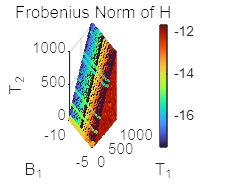

% Plotting the F-norm error
x = log10(K_err(:, 3));
z = K_err(:, 2);
y = K_err(:, 1);
error = K_err(:, 4);
log_error = log10(error);

h = scatter3(x, y, z, 5, log_error, 'filled');

colormap('Turbo');
colorbar;
alpha_val = 0.75;
set(h, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);

xlabel('B_1');
ylabel('T_1');
zlabel('T_2');
title('Frobenius Norm of H');
view(ax1, [20, 30]); 
grid on;

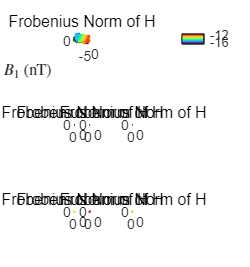

% Figure 1 
clear;clc;
close all;

B105 = load('F_norm_error_of_H/1e-05-Delta_51.mat');
B107 = load('F_norm_error_of_H/1e-07-Delta_51.mat');
B110 = load('F_norm_error_of_H/1e-10-Delta_51.mat');
B1Delta = load('F_norm_error_of_H/B1_101-Delta.mat');
B1050 = load('F_norm_error_of_H/1e-05-0.mat');
B1070 = load('F_norm_error_of_H/1e-07-0.mat');
B1100 = load('F_norm_error_of_H/1e-10-0.mat');

x1 = log10(B1Delta.K_err(:, 3));
z1 = B1Delta.K_err(:, 2);
y1 = B1Delta.K_err(:, 1);
error1 = B1Delta.K_err(:, 4);
log_error1 = log10(error1);

x2 = B110.K_err(:, 3);
z2 = B110.K_err(:, 2);
y2 = B110.K_err(:, 1);
error2 = B110.K_err(:, 4);
log_error2 = log10(error2);

x3 = B107.K_err(:, 3);
z3 = B107.K_err(:, 2);
y3 = B107.K_err(:, 1);
error3 = B107.K_err(:, 4);
log_error3 = log10(error3);

x4 = B105.K_err(:, 3);
z4 = B105.K_err(:, 2);
y4 = B105.K_err(:, 1);
error4 = B105.K_err(:, 4);
log_error4 = log10(error4);

x20 = B1100.K_err(:, 3);
z20 = B1100.K_err(:, 2);
y20 = B1100.K_err(:, 1);
error20 = B1100.K_err(:, 4);
log_error20 = log10(error20);

x30 = B1070.K_err(:, 3);
z30 = B1070.K_err(:, 2);
y30 = B1070.K_err(:, 1);
error30 = B1070.K_err(:, 4);
log_error30 = log10(error30);

x40 = B1050.K_err(:, 3);
z40 = B1050.K_err(:, 2);
y40 = B1050.K_err(:, 1);
error40 = B1050.K_err(:, 4);
log_error40 = log10(error40);


figure;
set(gcf, 'Units', 'centimeters', 'Position', [0 0 16.8 18]); 

t = tiledlayout(3, 3, 'TileSpacing', 'compact', ...
    'Padding', 'compact'); 
ax1 = nexttile(1, [1 3]); 
h1 = scatter3(ax1, x1, y1, z1, 2, log_error1, 'filled');
set(ax1, 'PlotBoxAspectRatio', [3 1.5 1]);  
set(ax1, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax1, 'Turbo');
clim(ax1, [-17, -11]);
colorbar;
alpha_val = 1;
set(h1, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax1, '$B_1$ (nT)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax1, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax1, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax1, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax1, [20, 30]); 
grid(ax1, 'on');
set(ax1, 'FontSize', 8); 
grid on;

ax2 = nexttile(7);
h2 = scatter3(ax2, x2, y2, z2, 0.8, log_error2, 'filled');
set(ax2, 'PlotBoxAspectRatio', [3 1.5 1]);
set(ax2, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax2, 'Turbo');
clim(ax2, [-17, -11]);
alpha_val = 1;
set(h2, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax2, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax2, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax2, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax2, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax2, [20, 30]);
grid(ax2, 'on');
set(ax2, 'FontSize', 8); 
grid on;

ax3 = nexttile(8);
h3 = scatter3(ax3, x3, y3, z3, 0.8, log_error3, 'filled');
set(ax3, 'PlotBoxAspectRatio', [3 1.5 1]); 
set(ax3, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax3, 'Turbo');
clim(ax3, [-17, -11]);
alpha_val = 1;
set(h3, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax3, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax3, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax3, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax3, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax3, [20, 30]); 
grid(ax3, 'on');
set(ax3, 'FontSize', 8); 
grid on;

ax4 = nexttile(9);
h4 = scatter3(ax4, x4, y4, z4, 0.8, log_error4, 'filled');
set(ax4, 'PlotBoxAspectRatio', [3 1.5 1]); 
set(ax4, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax4, 'Turbo');
clim(ax4, [-17, -11]);
alpha_val = 1;
set(h4, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax4, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax4, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax4, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax4, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax4, [20, 30]);
grid(ax4, 'on');
set(ax4, 'FontSize', 8); 
grid on;


ax20 = nexttile(4); 
h20 = scatter3(ax20, x20, y20, z20, 0.2, log_error20, 'filled');
set(ax20, 'PlotBoxAspectRatio', [3 1.5 1]); 
set(ax20, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax20, 'Turbo');
clim(ax20, [-17, -11]);
alpha_val = 1;
set(h20, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax20, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax20, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax20, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax20, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax20, [20, 30]);
grid(ax20, 'on');
set(ax20, 'FontSize', 8); 
grid on;

ax30 = nexttile(5); 
h30 = scatter3(ax30, x30, y30, z30, 0.2, log_error30, 'filled');
set(ax30, 'PlotBoxAspectRatio', [3 1.5 1]); 
set(ax30, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax30, 'Turbo');
clim(ax30, [-17, -11]);
alpha_val = 1;
set(h30, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax30, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax30, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax30, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax30, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax30, [20, 30]); 
grid(ax30, 'on');
set(ax30, 'FontSize', 8); 
grid on;

ax40 = nexttile(6); 
h40 = scatter3(ax40, x40, y40, z40, 0.2, log_error40, 'filled');
set(ax40, 'PlotBoxAspectRatio', [3 1.5 1]); 
set(ax40, 'PlotBoxAspectRatioMode', 'manual');
colormap(ax40, 'Turbo');
clim(ax40, [-17, -11]);
alpha_val = 1;
set(h4, 'MarkerFaceAlpha', alpha_val, 'MarkerEdgeAlpha', alpha_val);
xlabel(ax40, '$\Delta$ (rad/s)', 'Interpreter', 'latex', 'FontSize', 9);
ylabel(ax40, '$T_1$ (s)', 'Interpreter', 'latex', 'FontSize', 9);
zlabel(ax40, '$T_2$ (km)', 'Interpreter', 'latex', 'FontSize', 9);
title(ax40, 'Frobenius Norm of H', 'FontSize', 10, 'FontWeight', 'normal');
view(ax40, [20, 30]);
grid(ax40, 'on');
set(ax40, 'FontSize', 8); 
grid on;